# **Dylan Thornburg ECEN 133 HW7**

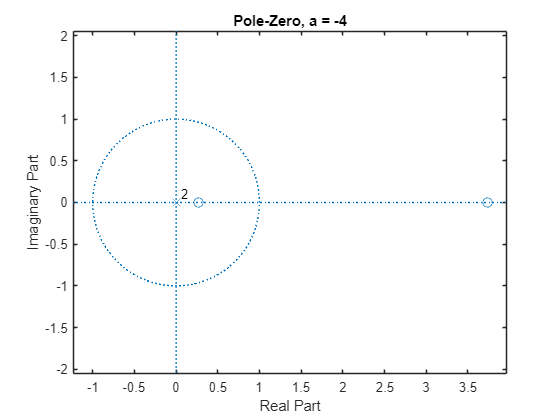

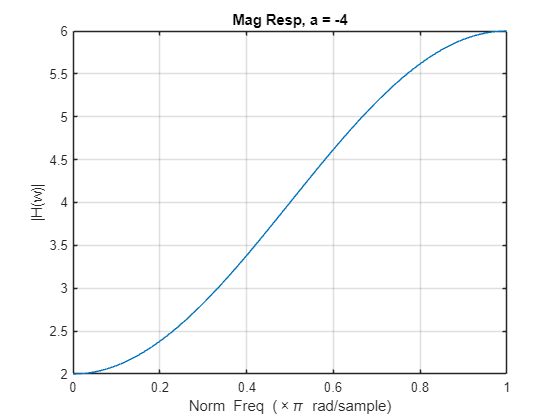

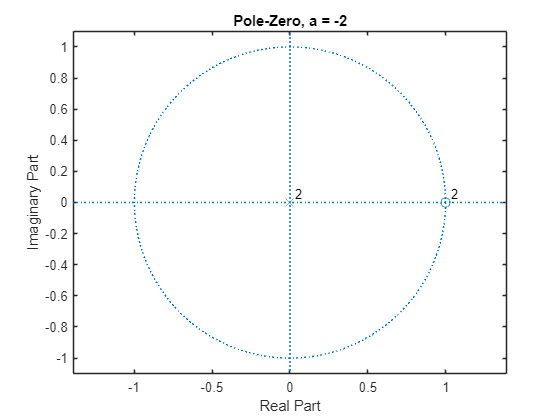

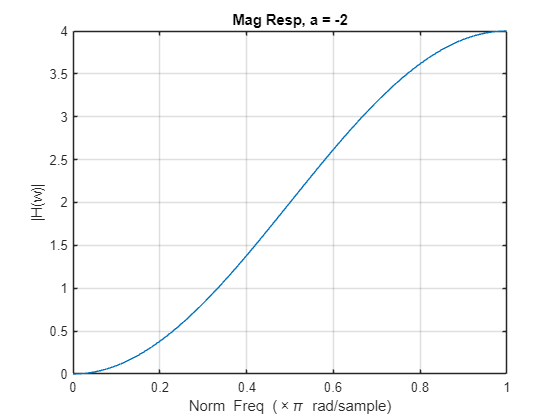

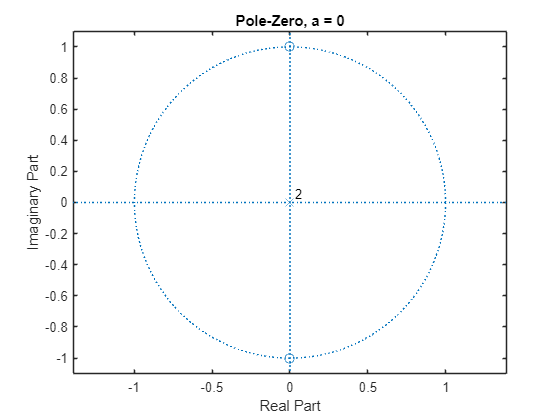

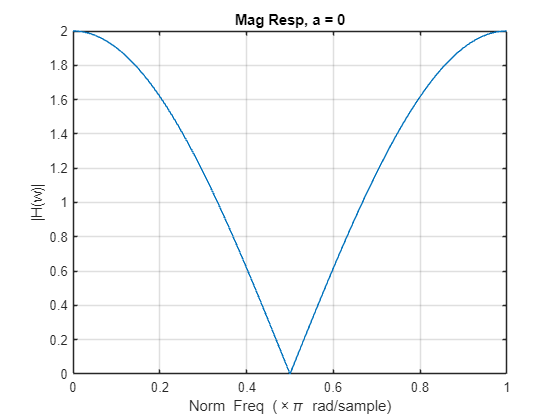

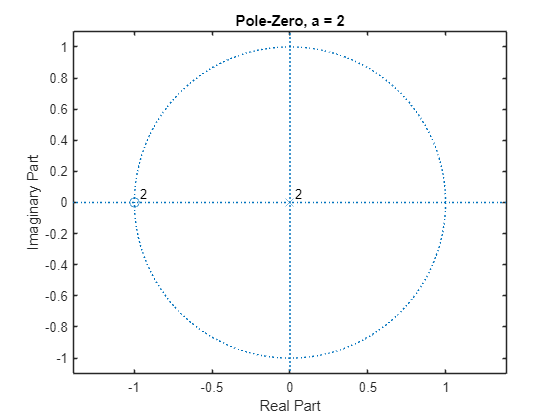

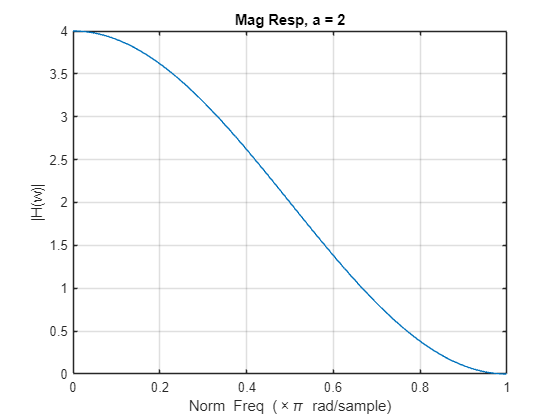

a = [-4, -2, 0, 2, 4];
Fs = 1024;

figure;
for i = 1:length(a)
    a1 = a(i);
    num = [1, a1, 1];   
    denom = [1, 0, 0];       

    z = roots(num);
    p = roots(denom);

    figure;
    zplane(z, p);
    title(['Pole-Zero, a = ', num2str(a1)]);

    [H, w] = freqz(num, denom, Fs);
    mag = abs(H);
    figure;
    plot(w/pi, mag);
    grid on;
    xlabel('Norm Freq (\times\pi rad/sample)');
    ylabel('|H(w)|');
    title(['Mag Resp, a = ', num2str(a1)]);
end

a=4,2 -> high pass

a=-4,-2 -> low pass

a=0 -> neither

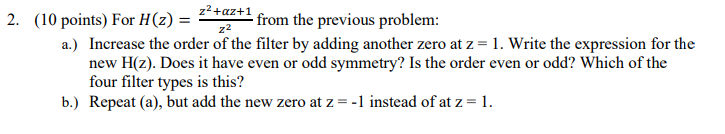

**Part A.**

H(z) = (z^2 + az + 1)(z-1)/z^2

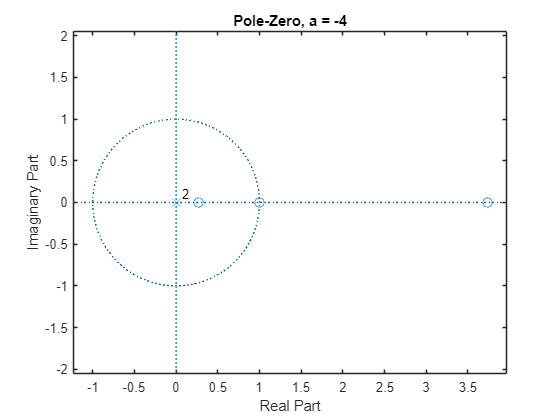

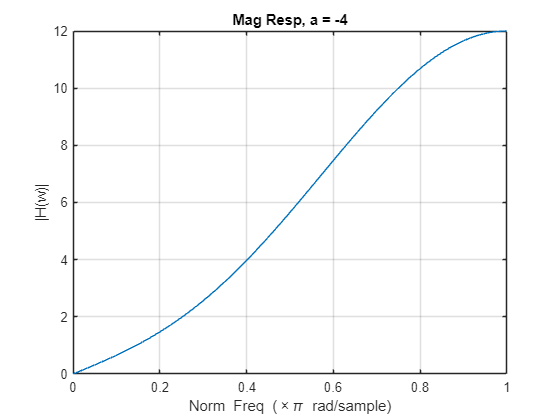

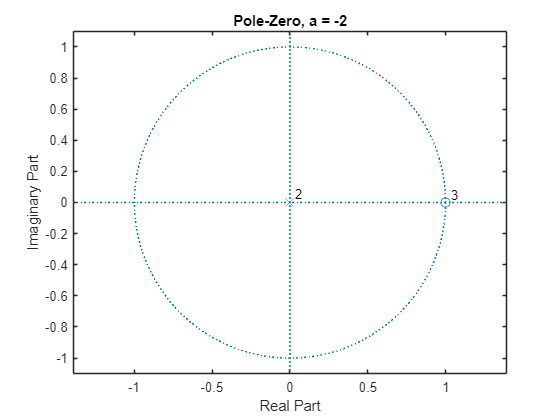

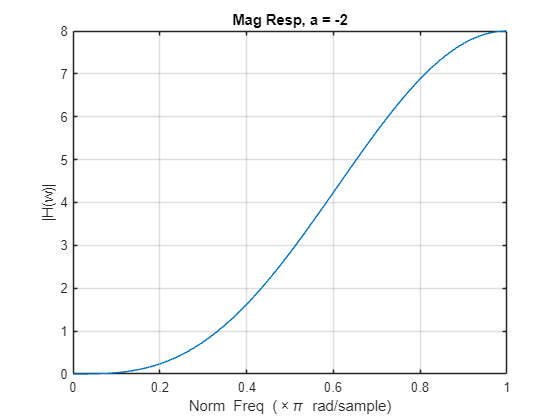

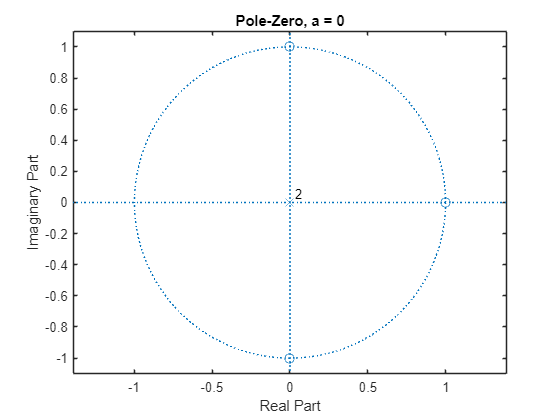

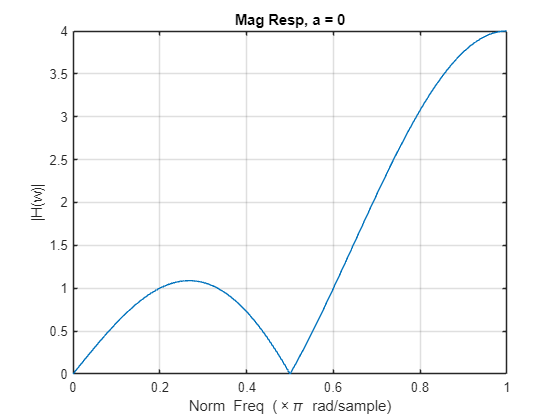

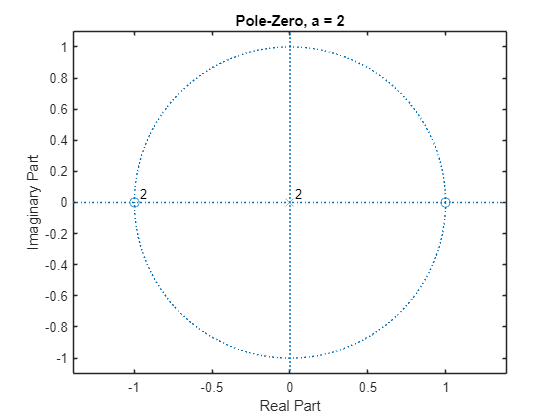

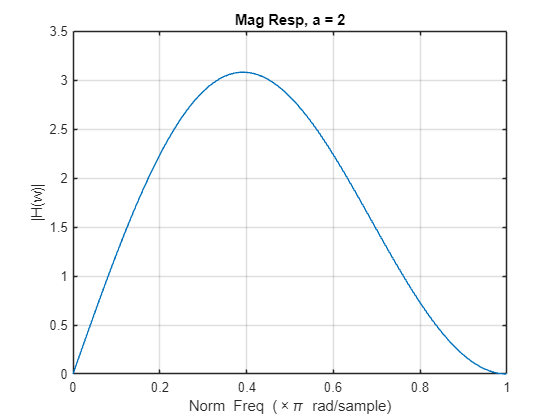

a = [-4, -2, 0, 2, 4];
Fs = 1024;

figure;
for i = 1:length(a)
    a1 = a(i);
    num = [1, (a1-1), (1-a1), -1];   
    denom = [1, 0, 0];       

    z = roots(num);
    p = roots(denom);

    figure;
    zplane(z, p);
    title(['Pole-Zero, a = ', num2str(a1)]);

    [H, w] = freqz(num, denom, Fs);
    mag = abs(H);
    figure;
    plot(w/pi, mag);
    grid on;
    xlabel('Norm Freq (\times\pi rad/sample)');
    ylabel('|H(w)|');
    title(['Mag Resp, a = ', num2str(a1)]);
end

Odd symmetry with an odd order because 3 zeros. High pass.

**Part B. **

H(z) = (z^2 + az + 1)(z+1)/z^2

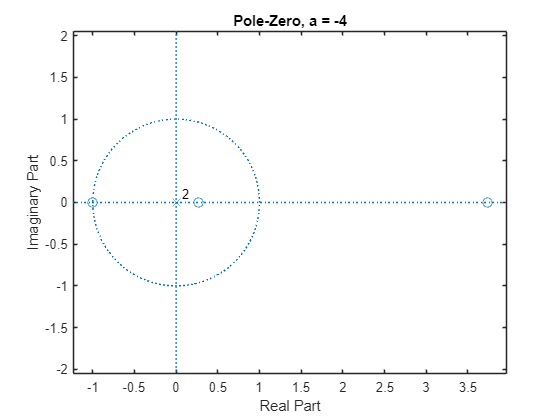

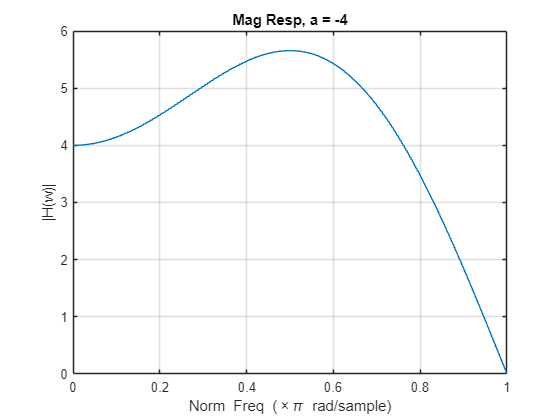

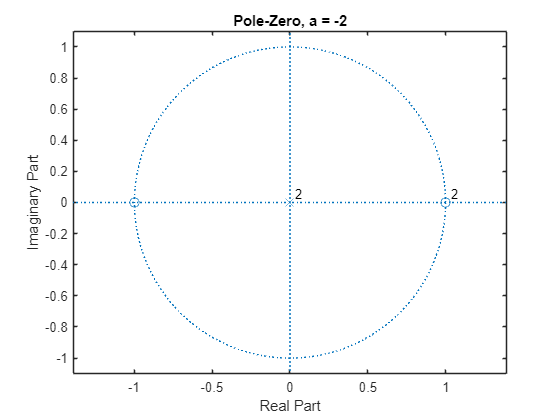

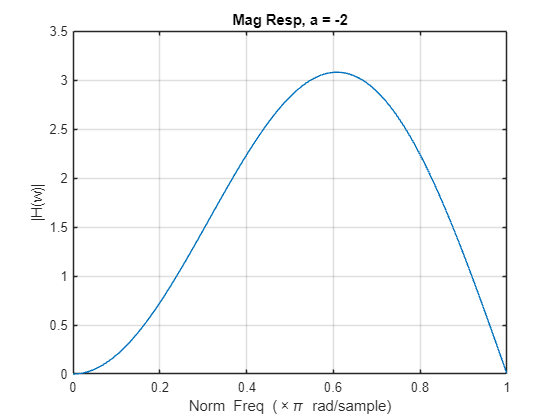

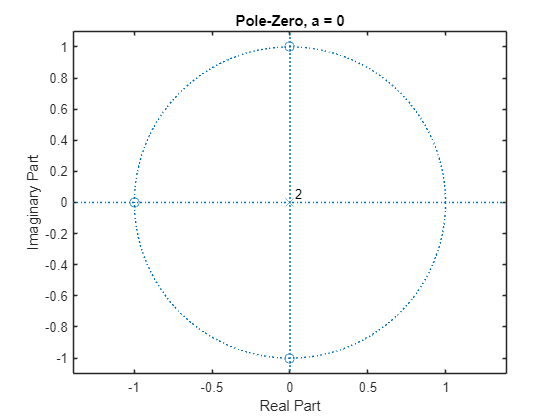

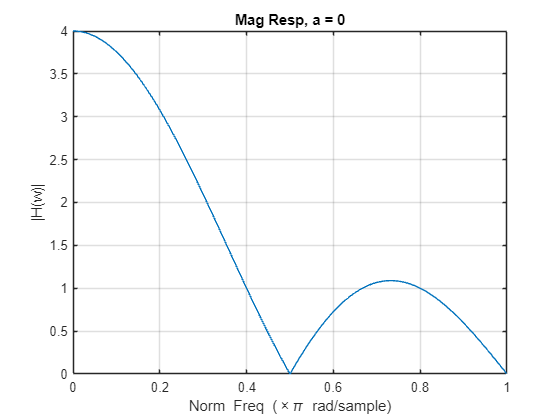

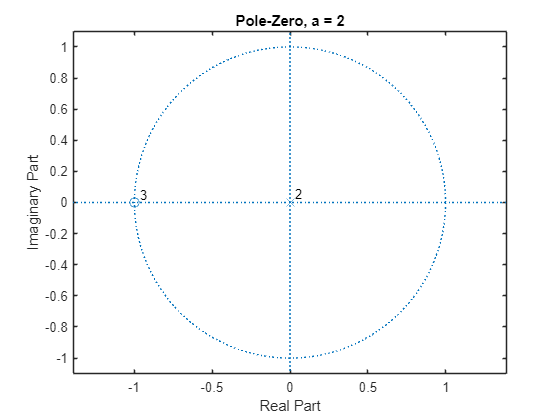

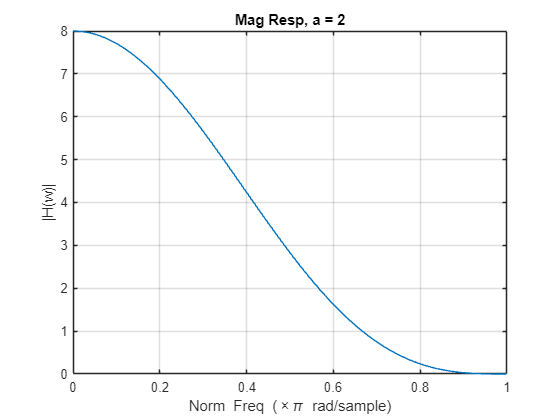

a = [-4, -2, 0, 2, 4];
Fs = 1024;

figure;
for i = 1:length(a)
    a1 = a(i);
    num = [1, (a1+1), (1+a1), 1];   
    denom = [1, 0, 0];       

    z = roots(num);
    p = roots(denom);

    figure;
    zplane(z, p);
    title(['Pole-Zero, a = ', num2str(a1)]);

    [H, w] = freqz(num, denom, Fs);
    mag = abs(H);
    figure;
    plot(w/pi, mag);
    grid on;
    xlabel('Norm Freq (\times\pi rad/sample)');
    ylabel('|H(w)|');
    title(['Mag Resp, a = ', num2str(a1)]);
end

Even symmetry with an odd order. Low Pass.

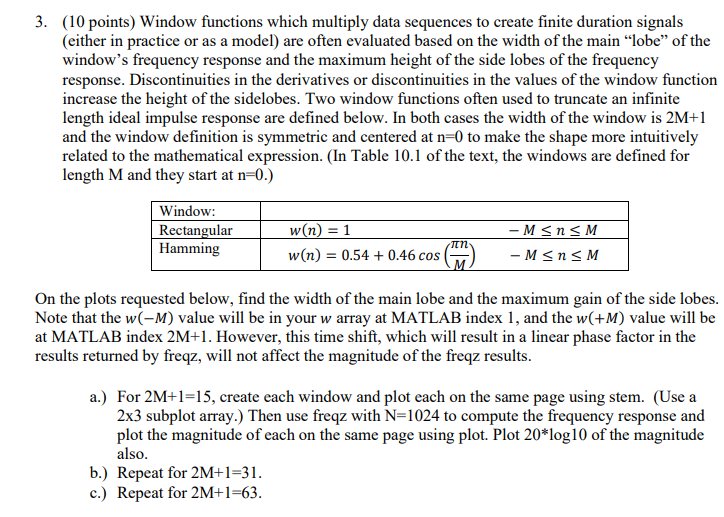

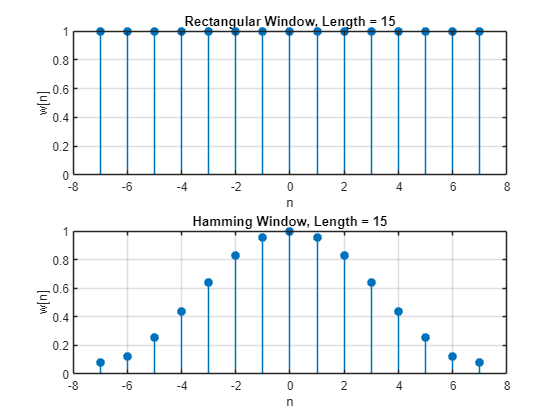

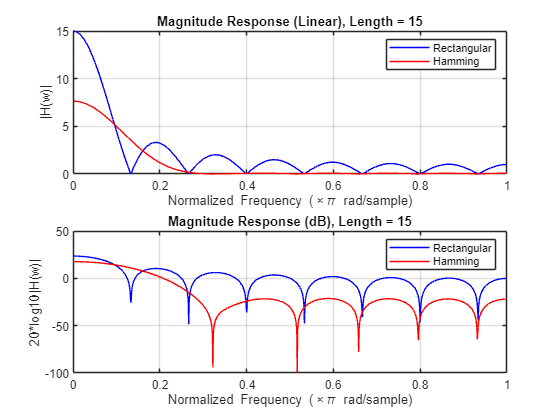

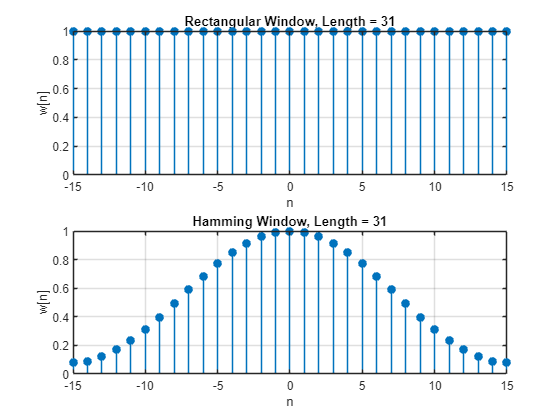

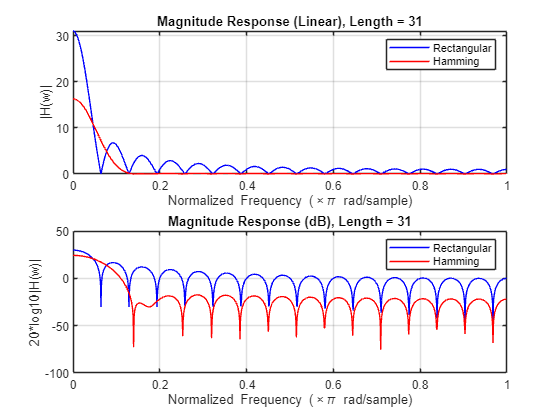

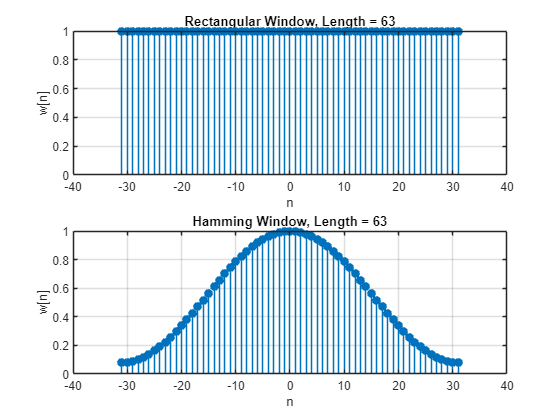

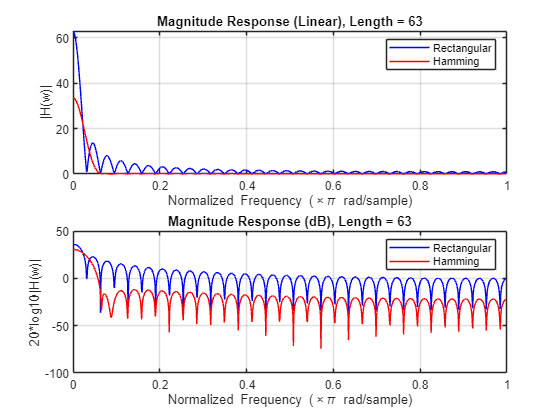

Ms = [7, 15, 31]; % for lengths 15, 31, 63 (2M+1) = length
N = 1024;

for k = 1:length(Ms)
    M = Ms(k);
    L = 2*M + 1;
    n = -M:M;

    %windows
    rect = ones(1, L);
    hamming = 0.54 + 0.46 * cos(pi * n / M);

    figure('Name', ['Window Time-Domain, Length = ', num2str(L)], 'NumberTitle', 'off');
    subplot(2,1,1);
    stem(n, rect, 'filled');
    title(['Rectangular Window, Length = ', num2str(L)]);
    xlabel('n'); 
    ylabel('w[n]');
    grid on;

    subplot(2,1,2);
    stem(n, hamming, 'filled');
    title(['Hamming Window, Length = ', num2str(L)]);
    xlabel('n'); 
    ylabel('w[n]');
    grid on;

    [H_rect, w] = freqz(rect, 1, N);
    [H_ham, ~] = freqz(hamming, 1, N);

    figure('Name', ['Magnitude Response, Length = ', num2str(L)], 'NumberTitle', 'off');
    subplot(2,1,1);
    plot(w/pi, abs(H_rect), 'b', 'DisplayName', 'Rectangular'); 
    hold on;
    plot(w/pi, abs(H_ham), 'r', 'DisplayName', 'Hamming');
    title(['Magnitude Response (Linear), Length = ', num2str(L)]);
    xlabel('Normalized Frequency (\times\pi rad/sample)');
    ylabel('|H(w)|');
    legend; 
    grid on;

    subplot(2,1,2);
    plot(w/pi, 20*log10(abs(H_rect + 1e-13)), 'b', 'DisplayName', 'Rectangular'); 
    hold on;
    plot(w/pi, 20*log10(abs(H_ham + 1e-13)), 'r', 'DisplayName', 'Hamming');
    title(['Magnitude Response (dB), Length = ', num2str(L)]);
    xlabel('Normalized Frequency (\times\pi rad/sample)');
    ylabel('20*log10|H(w)|');
    legend; 
    grid on;
end

a. rectangular main lobe width = .27 rad/sample

    rectangular magnitude (dB) = 10

    hamming main lobe width = .64 rad/sample

    hamming magnitude (dB) = -22

b. rectangular main lobe width = .13 rad/sample

    rectangular magnitude (dB) = 16.5

    hamming main lobe width = .28 rad/sample

    hamming magnitude (dB) = -17.5

c. rectangular main lobe width = .06 rad/sample

    rectangular magnitude (dB) = 22.7

    hamming main lobe width = .13 rad/sample

    hamming magnitude (dB) = -12.5

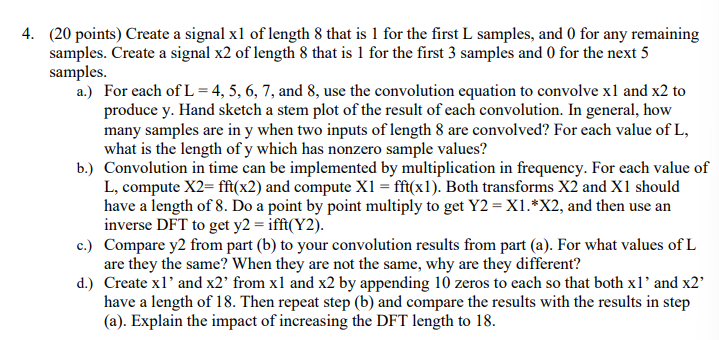

The instructions say to hand sketch but I'm not going to. I'll tank the point deduction.

Part a

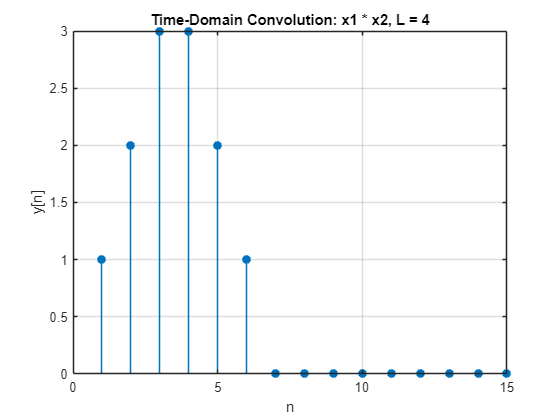

Part b

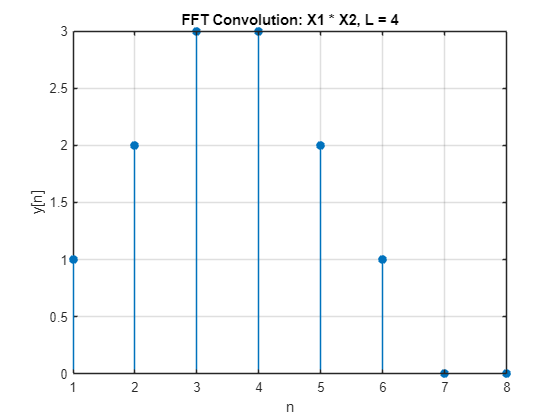

Part d

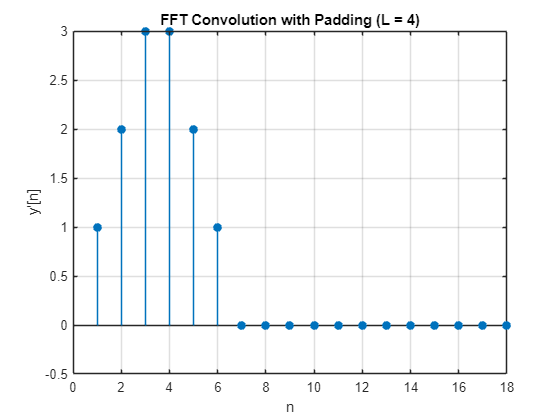

Part a

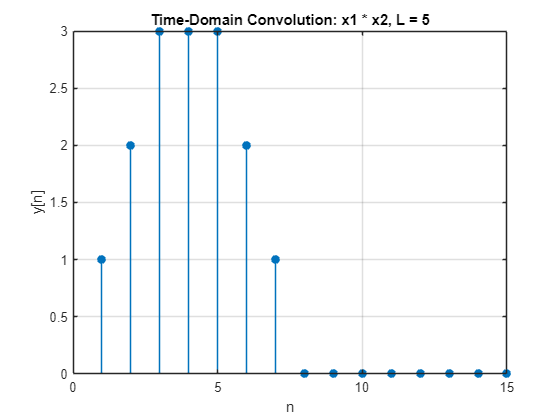

Part b

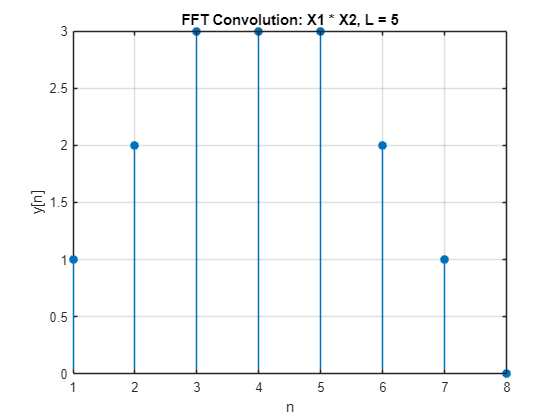

Part d

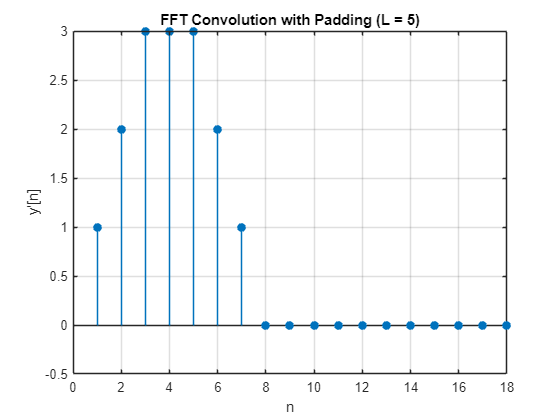

Part a

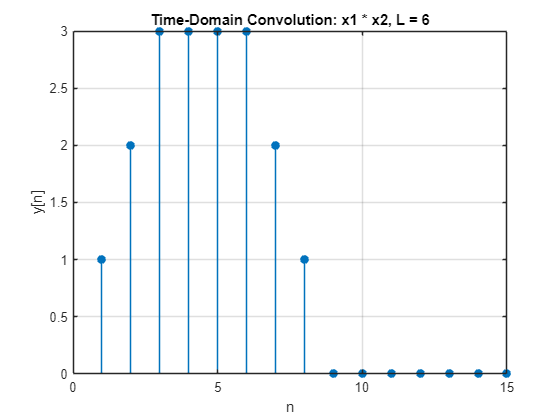

Part b

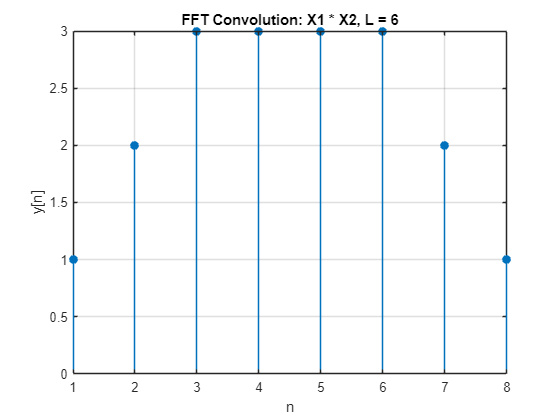

Part d

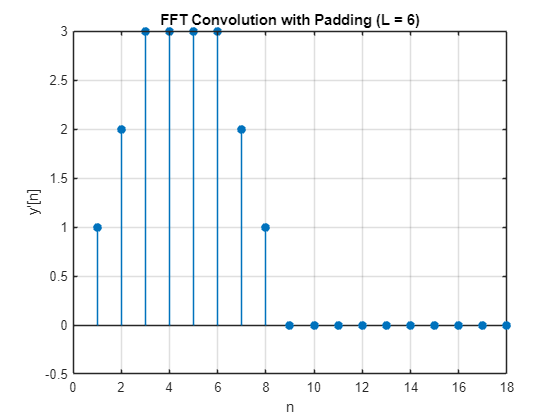

Part a

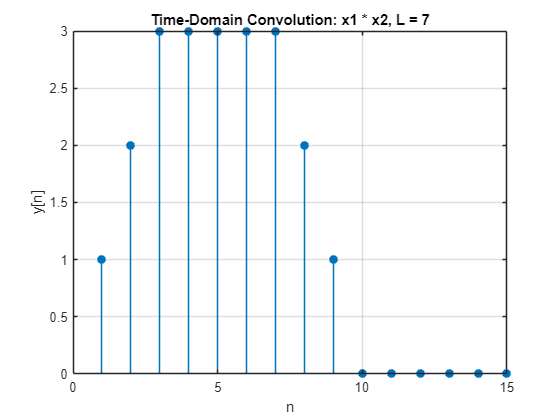

Part b

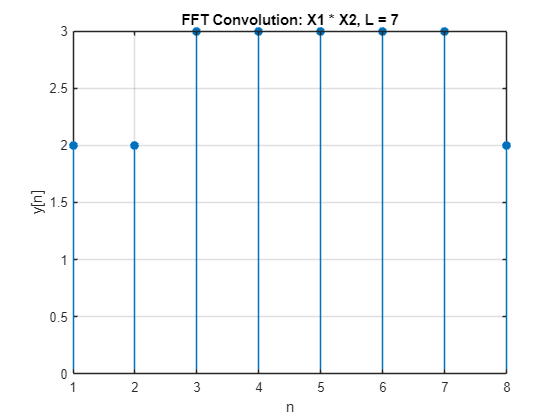

Part d

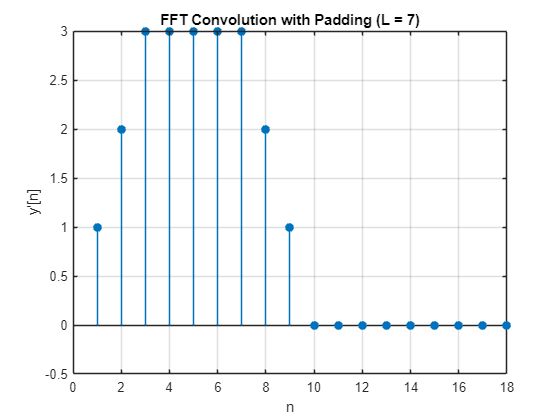

Part a

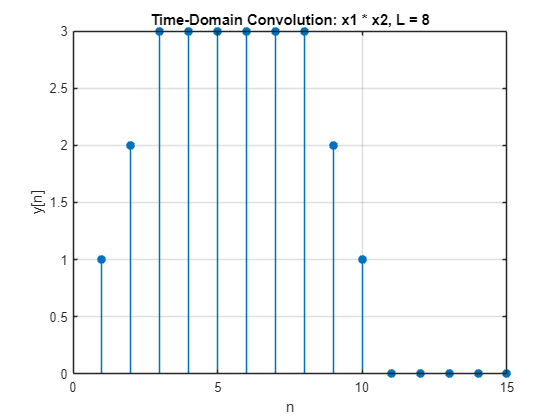

Part b

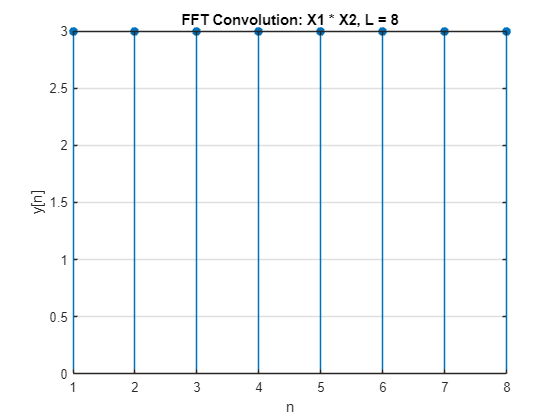

Part d

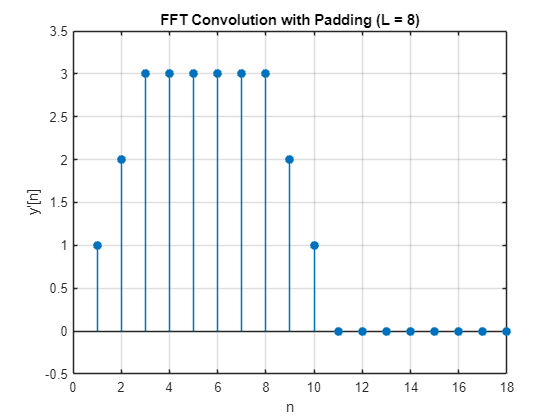

L_values = 4:8;
x2 = [1, 1, 1, 0, 0, 0, 0, 0]; 
for L = L_values
    % make x1 with L ones and the rest zeros (length = 8)
    x1 = [ones(1, L), zeros(1, 8 - L)];
    y_conv = conv(x1, x2);
    fprintf('Part a');
    figure;
    stem(y_conv, 'filled');
    title(['Time-Domain Convolution: x1 * x2, L = ', num2str(L)]);
    xlabel('n'); ylabel('y[n]');
    grid on;

    %part b
    X1 = fft(x1, 8);  
    X2 = fft(x2, 8);
    Y2 = X1 .* X2;
    y2 = ifft(Y2);
    fprintf('Part b');
    figure;
    stem(y2, 'filled');
    title(['FFT Convolution: X1 * X2, L = ', num2str(L)]);
    xlabel('n'); ylabel('y[n]');
    grid on;

    fprintf('Part d');
    x1p = [x1 zeros(1, 10)];
    x2p = [x2 zeros(1, 10)];
    X1p = fft(x1p);
    X2p = fft(x2p);
    Yp = X1p .* X2p;
    yp = ifft(Yp);

    figure;
    stem(yp, 'filled');
    title(['FFT Convolution with Padding (L = ', num2str(L), ')']);
    xlabel('n'); ylabel('y''[n]');
    grid on;
end

For L = 4,5,6, we get all the same values, though at different n's. Once we move to L=7,8 we get some aliasing due to the nature of circular convolution. The zero padding on part d helps us simulate linear convolution instead of circular convolution. In fact we have more space than necessary (18>15). (2*8-1)-8 zeroes are the minimum we'd need for linear convolution.

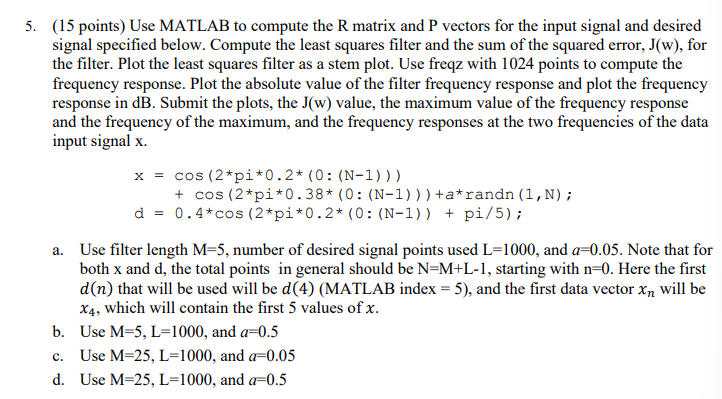

Part a

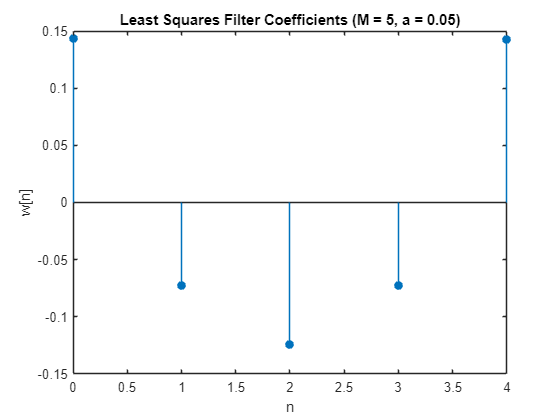

M = 5;
L = 1000;
a = 0.05;
N = M + L - 1;
n = 0:N-1;

x = cos(2*pi*0.2*n) + cos(2*pi*0.38*n) + a*randn(1, N);
d = 0.4*cos(2*pi*0.2*n + pi/5);

% Construct matrix X (each row: x_n to x_{n+M-1})
X = zeros(L, M);
for i = 1:L
    X(i, :) = x(i+M-1:-1:i);  % Time-reversed window
end

d_vec = d(M:end)';  % Length-L vector of desired outputs

% Least squares solution
R = X' * X;
P = X' * d_vec;
w = R \ P;  % Filter coefficients

% Sum of squared error
J = norm(X*w - d_vec)^2;

%impulse response
figure;
stem(0:M-1, w, 'filled');
title(['Least Squares Filter Coefficients (M = ', num2str(M), ', a = ', num2str(a), ')']);
xlabel('n'); ylabel('w[n]');

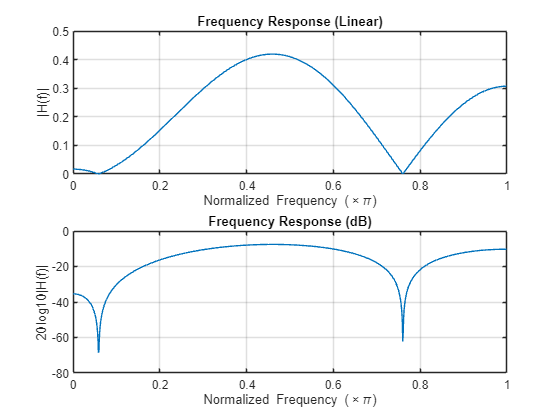


[H, f] = freqz(w, 1, 1024);
mag = abs(H);
mag_dB = 20*log10(mag);

%Frequency Response (abs)
figure;
subplot(2,1,1);
plot(f/pi, mag);
title('Frequency Response (Linear)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('|H(f)|');
grid on;

subplot(2,1,2);
plot(f/pi, mag_dB);
title('Frequency Response (dB)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('20log10|H(f)|');
grid on;


[max_gain, idx_max] = max(mag);
f_max = f(idx_max)/pi;

[H_check, ~] = freqz(w, 1, [0.2 0.38]*pi);
gain_at_02 = abs(H_check(1));
gain_at_024 = abs(H_check(2));

fprintf('M = %d, a = %.2f\n', M, a);

M = 5, a = 0.05


fprintf('Sum of squared error J(w): %.4f\n', J);

Sum of squared error J(w): 0.1562


fprintf('Max gain: %.4f at normalized freq = %.4fπ\n', max_gain, f_max);

Max gain: 0.4191 at normalized freq = 0.4600π


fprintf('Gain at 0.2π: %.4f\n', gain_at_02);

Gain at 0.2π: 0.1529


fprintf('Gain at 0.38π: %.4f\n', gain_at_024);

Gain at 0.38π: 0.3858


Part b

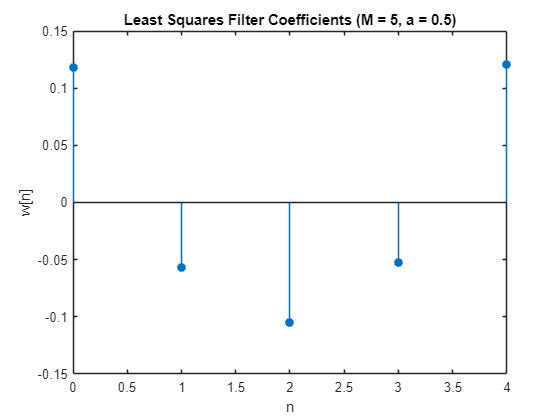

M = 5;
L = 1000;
a = 0.5;
N = M + L - 1;
n = 0:N-1;

x = cos(2*pi*0.2*n) + cos(2*pi*0.38*n) + a*randn(1, N);
d = 0.4*cos(2*pi*0.2*n + pi/5);

% Construct matrix X (each row: x_n to x_{n+M-1})
X = zeros(L, M);
for i = 1:L
    X(i, :) = x(i+M-1:-1:i);  % Time-reversed window
end

d_vec = d(M:end)';  % Length-L vector of desired outputs

% Least squares solution
R = X' * X;
P = X' * d_vec;
w = R \ P;  % Filter coefficients

% Sum of squared error
J = norm(X*w - d_vec)^2;

%impulse response
figure;
stem(0:M-1, w, 'filled');
title(['Least Squares Filter Coefficients (M = ', num2str(M), ', a = ', num2str(a), ')']);
xlabel('n'); ylabel('w[n]');

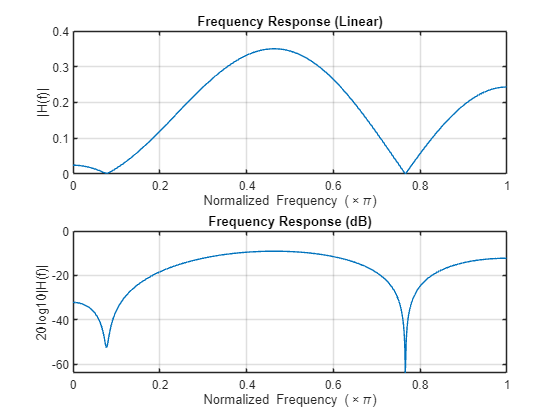


[H, f] = freqz(w, 1, 1024);
mag = abs(H);
mag_dB = 20*log10(mag);

%Frequency Response (abs)
figure;
subplot(2,1,1);
plot(f/pi, mag);
title('Frequency Response (Linear)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('|H(f)|');
grid on;

subplot(2,1,2);
plot(f/pi, mag_dB);
title('Frequency Response (dB)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('20log10|H(f)|');
grid on;


[max_gain, idx_max] = max(mag);
f_max = f(idx_max)/pi;

[H_check, ~] = freqz(w, 1, [0.2 0.38]*pi);
gain_at_02 = abs(H_check(1));
gain_at_024 = abs(H_check(2));

fprintf('M = %d, a = %.2f\n', M, a);

M = 5, a = 0.50


fprintf('Sum of squared error J(w): %.4f\n', J);

Sum of squared error J(w): 13.0398


fprintf('Max gain: %.4f at normalized freq = %.4fπ\n', max_gain, f_max);

Max gain: 0.3503 at normalized freq = 0.4639π


fprintf('Gain at 0.2π: %.4f\n', gain_at_02);

Gain at 0.2π: 0.1198


fprintf('Gain at 0.38π: %.4f\n', gain_at_024);

Gain at 0.38π: 0.3195


part c

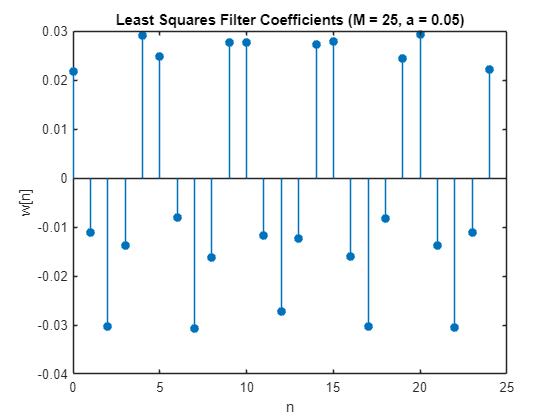

M = 25;
L = 1000;
a = 0.05;
N = M + L - 1;
n = 0:N-1;

x = cos(2*pi*0.2*n) + cos(2*pi*0.38*n) + a*randn(1, N);
d = 0.4*cos(2*pi*0.2*n + pi/5);

% Construct matrix X (each row: x_n to x_{n+M-1})
X = zeros(L, M);
for i = 1:L
    X(i, :) = x(i+M-1:-1:i);  % Time-reversed window
end

d_vec = d(M:end)';  % Length-L vector of desired outputs

% Least squares solution
R = X' * X;
P = X' * d_vec;
w = R \ P;  % Filter coefficients

% Sum of squared error
J = norm(X*w - d_vec)^2;

%impulse response
figure;
stem(0:M-1, w, 'filled');
title(['Least Squares Filter Coefficients (M = ', num2str(M), ', a = ', num2str(a), ')']);
xlabel('n'); ylabel('w[n]');

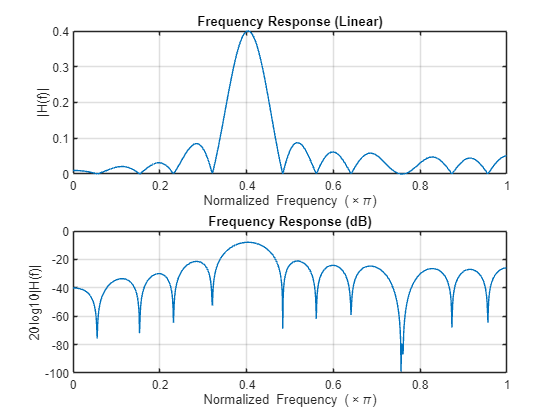


[H, f] = freqz(w, 1, 1024);
mag = abs(H);
mag_dB = 20*log10(mag);

%Frequency Response (abs)
figure;
subplot(2,1,1);
plot(f/pi, mag);
title('Frequency Response (Linear)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('|H(f)|');
grid on;

subplot(2,1,2);
plot(f/pi, mag_dB);
title('Frequency Response (dB)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('20log10|H(f)|');
grid on;


[max_gain, idx_max] = max(mag);
f_max = f(idx_max)/pi;

[H_check, ~] = freqz(w, 1, [0.2 0.38]*pi);
gain_at_02 = abs(H_check(1));
gain_at_024 = abs(H_check(2));

fprintf('M = %d, a = %.2f\n', M, a);

M = 25, a = 0.05


fprintf('Sum of squared error J(w): %.4f\n', J);

Sum of squared error J(w): 0.0323


fprintf('Max gain: %.4f at normalized freq = %.4fπ\n', max_gain, f_max);

Max gain: 0.4000 at normalized freq = 0.4033π


fprintf('Gain at 0.2π: %.4f\n', gain_at_02);

Gain at 0.2π: 0.0314


fprintf('Gain at 0.38π: %.4f\n', gain_at_024);

Gain at 0.38π: 0.3478


part d

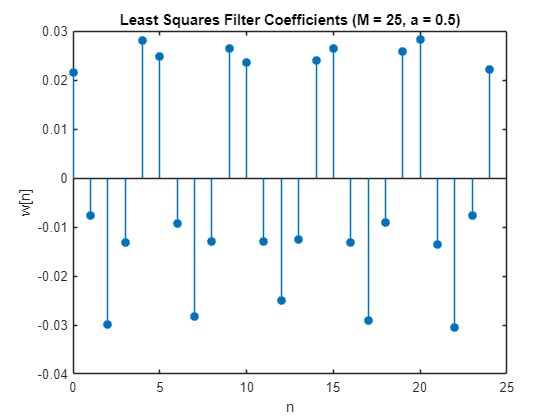

M = 25;
L = 1000;
a = 0.5;
N = M + L - 1;
n = 0:N-1;

x = cos(2*pi*0.2*n) + cos(2*pi*0.38*n) + a*randn(1, N);
d = 0.4*cos(2*pi*0.2*n + pi/5);

% Construct matrix X (each row: x_n to x_{n+M-1})
X = zeros(L, M);
for i = 1:L
    X(i, :) = x(i+M-1:-1:i);  % Time-reversed window
end

d_vec = d(M:end)';  % Length-L vector of desired outputs

% Least squares solution
R = X' * X;
P = X' * d_vec;
w = R \ P;  % Filter coefficients

% Sum of squared error
J = norm(X*w - d_vec)^2;

%impulse response
figure;
stem(0:M-1, w, 'filled');
title(['Least Squares Filter Coefficients (M = ', num2str(M), ', a = ', num2str(a), ')']);
xlabel('n'); ylabel('w[n]');

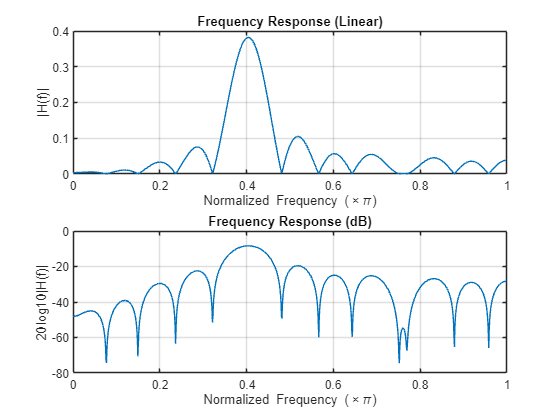


[H, f] = freqz(w, 1, 1024);
mag = abs(H);
mag_dB = 20*log10(mag);

%Frequency Response (abs)
figure;
subplot(2,1,1);
plot(f/pi, mag);
title('Frequency Response (Linear)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('|H(f)|');
grid on;

subplot(2,1,2);
plot(f/pi, mag_dB);
title('Frequency Response (dB)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('20log10|H(f)|');
grid on;


[max_gain, idx_max] = max(mag);
f_max = f(idx_max)/pi;

[H_check, ~] = freqz(w, 1, [0.2 0.38]*pi);
gain_at_02 = abs(H_check(1));
gain_at_024 = abs(H_check(2));

fprintf('M = %d, a = %.2f\n', M, a);

M = 25, a = 0.50


fprintf('Sum of squared error J(w): %.4f\n', J);

Sum of squared error J(w): 2.9126


fprintf('Max gain: %.4f at normalized freq = %.4fπ\n', max_gain, f_max);

Max gain: 0.3819 at normalized freq = 0.4043π


fprintf('Gain at 0.2π: %.4f\n', gain_at_02);

Gain at 0.2π: 0.0333


fprintf('Gain at 0.38π: %.4f\n', gain_at_024);

Gain at 0.38π: 0.3283


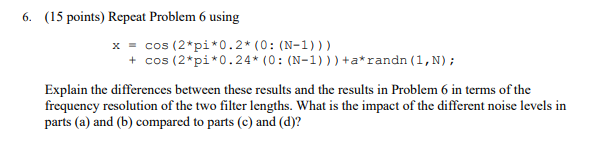

part a

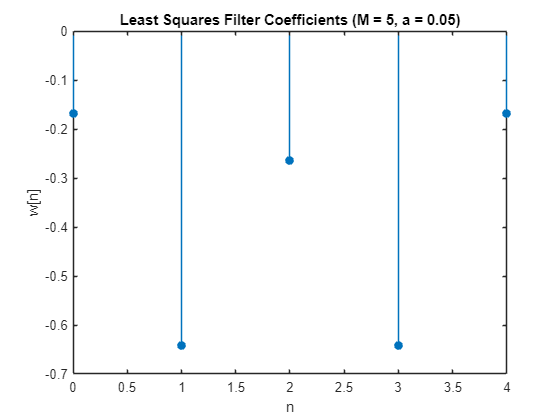

M = 5;
L = 1000;
a = 0.05;
N = M + L - 1;
n = 0:N-1;

x = cos(2*pi*0.2*n) + cos(2*pi*0.24*n) + a*randn(1, N);
d = 0.4*cos(2*pi*0.2*n + pi/5);

% Construct matrix X (each row: x_n to x_{n+M-1})
X = zeros(L, M);
for i = 1:L
    X(i, :) = x(i+M-1:-1:i);  % Time-reversed window
end

d_vec = d(M:end)';  % Length-L vector of desired outputs

% Least squares solution
R = X' * X;
P = X' * d_vec;
w = R \ P;  % Filter coefficients

% Sum of squared error
J = norm(X*w - d_vec)^2;

%impulse response
figure;
stem(0:M-1, w, 'filled');
title(['Least Squares Filter Coefficients (M = ', num2str(M), ', a = ', num2str(a), ')']);
xlabel('n'); ylabel('w[n]');

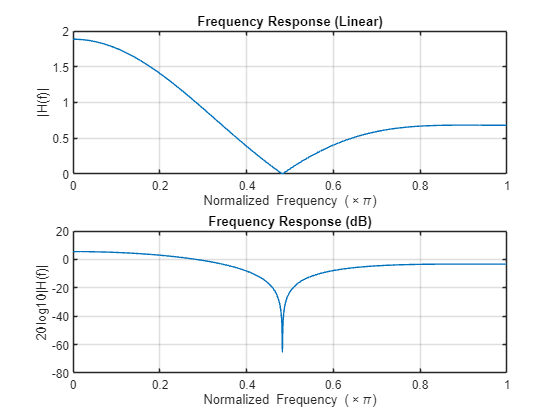


[H, f] = freqz(w, 1, 1024);
mag = abs(H);
mag_dB = 20*log10(mag);

%Frequency Response (abs)
figure;
subplot(2,1,1);
plot(f/pi, mag);
title('Frequency Response (Linear)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('|H(f)|');
grid on;

subplot(2,1,2);
plot(f/pi, mag_dB);
title('Frequency Response (dB)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('20log10|H(f)|');
grid on;


[max_gain, idx_max] = max(mag);
f_max = f(idx_max)/pi;

[H_check, ~] = freqz(w, 1, [0.2 0.24]*pi);
gain_at_02 = abs(H_check(1));
gain_at_024 = abs(H_check(2));

fprintf('M = %d, a = %.2f\n', M, a);

M = 5, a = 0.05


fprintf('Sum of squared error J(w): %.4f\n', J);

Sum of squared error J(w): 2.4478


fprintf('Max gain: %.4f at normalized freq = %.4fπ\n', max_gain, f_max);

Max gain: 1.8849 at normalized freq = 0.0000π


fprintf('Gain at 0.2π: %.4f\n', gain_at_02);

Gain at 0.2π: 1.4070


fprintf('Gain at 0.24π: %.4f\n', gain_at_024);

Gain at 0.24π: 1.2213


part b

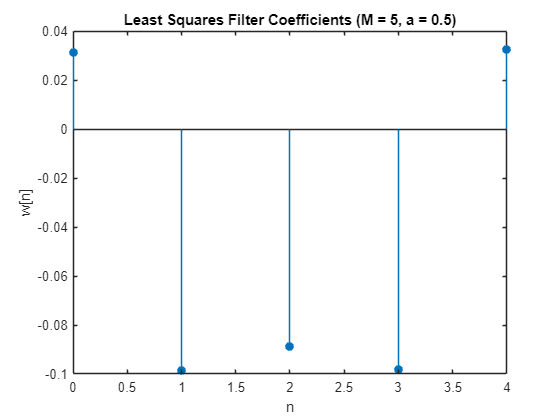

M = 5;
L = 1000;
a = 0.5;
N = M + L - 1;
n = 0:N-1;

x = cos(2*pi*0.2*n) + cos(2*pi*0.24*n) + a*randn(1, N);
d = 0.4*cos(2*pi*0.2*n + pi/5);

% Construct matrix X (each row: x_n to x_{n+M-1})
X = zeros(L, M);
for i = 1:L
    X(i, :) = x(i+M-1:-1:i);  % Time-reversed window
end

d_vec = d(M:end)';  % Length-L vector of desired outputs

% Least squares solution
R = X' * X;
P = X' * d_vec;
w = R \ P;  % Filter coefficients

% Sum of squared error
J = norm(X*w - d_vec)^2;

%impulse response
figure;
stem(0:M-1, w, 'filled');
title(['Least Squares Filter Coefficients (M = ', num2str(M), ', a = ', num2str(a), ')']);
xlabel('n'); ylabel('w[n]');

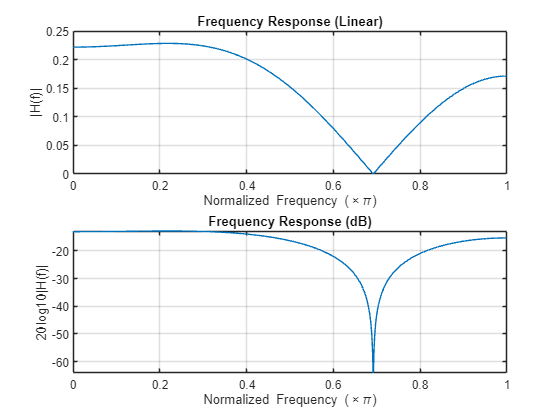


[H, f] = freqz(w, 1, 1024);
mag = abs(H);
mag_dB = 20*log10(mag);

%Frequency Response (abs)
figure;
subplot(2,1,1);
plot(f/pi, mag);
title('Frequency Response (Linear)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('|H(f)|');
grid on;

subplot(2,1,2);
plot(f/pi, mag_dB);
title('Frequency Response (dB)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('20log10|H(f)|');
grid on;


[max_gain, idx_max] = max(mag);
f_max = f(idx_max)/pi;

[H_check, ~] = freqz(w, 1, [0.2 0.24]*pi);
gain_at_02 = abs(H_check(1));
gain_at_024 = abs(H_check(2));

fprintf('M = %d, a = %.2f\n', M, a);

M = 5, a = 0.50


fprintf('Sum of squared error J(w): %.4f\n', J);

Sum of squared error J(w): 40.4339


fprintf('Max gain: %.4f at normalized freq = %.4fπ\n', max_gain, f_max);

Max gain: 0.2283 at normalized freq = 0.2188π


fprintf('Gain at 0.2π: %.4f\n', gain_at_02);

Gain at 0.2π: 0.2282


fprintf('Gain at 0.24π: %.4f\n', gain_at_024);

Gain at 0.24π: 0.2281


part c

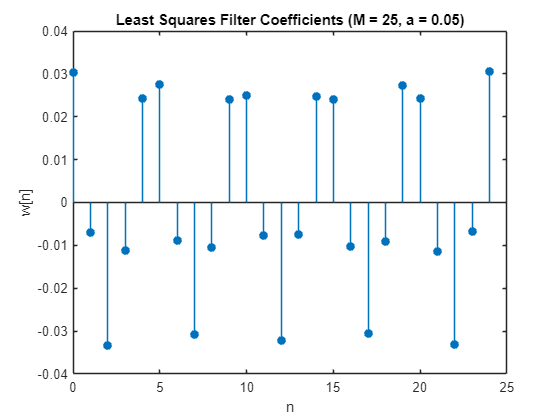

M = 25;
L = 1000;
a = 0.05;
N = M + L - 1;
n = 0:N-1;

x = cos(2*pi*0.2*n) + cos(2*pi*0.24*n) + a*randn(1, N);
d = 0.4*cos(2*pi*0.2*n + pi/5);

% Construct matrix X (each row: x_n to x_{n+M-1})
X = zeros(L, M);
for i = 1:L
    X(i, :) = x(i+M-1:-1:i);  % Time-reversed window
end

d_vec = d(M:end)';  % Length-L vector of desired outputs

% Least squares solution
R = X' * X;
P = X' * d_vec;
w = R \ P;  % Filter coefficients

% Sum of squared error
J = norm(X*w - d_vec)^2;

%impulse response
figure;
stem(0:M-1, w, 'filled');
title(['Least Squares Filter Coefficients (M = ', num2str(M), ', a = ', num2str(a), ')']);
xlabel('n'); ylabel('w[n]');

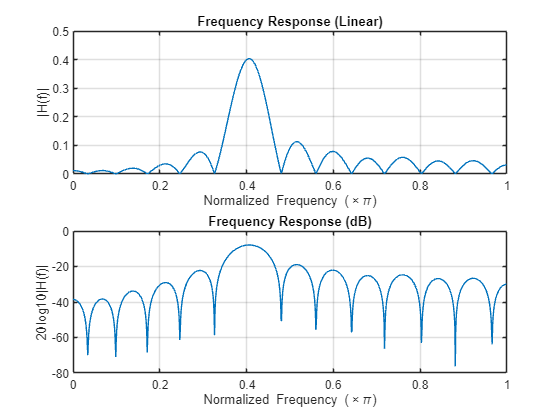


[H, f] = freqz(w, 1, 1024);
mag = abs(H);
mag_dB = 20*log10(mag);

%Frequency Response (abs)
figure;
subplot(2,1,1);
plot(f/pi, mag);
title('Frequency Response (Linear)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('|H(f)|');
grid on;

subplot(2,1,2);
plot(f/pi, mag_dB);
title('Frequency Response (dB)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('20log10|H(f)|');
grid on;


[max_gain, idx_max] = max(mag);
f_max = f(idx_max)/pi;

[H_check, ~] = freqz(w, 1, [0.2 0.24]*pi);
gain_at_02 = abs(H_check(1));
gain_at_024 = abs(H_check(2));

fprintf('M = %d, a = %.2f\n', M, a);

M = 25, a = 0.05


fprintf('Sum of squared error J(w): %.4f\n', J);

Sum of squared error J(w): 0.0261


fprintf('Max gain: %.4f at normalized freq = %.4fπ\n', max_gain, f_max);

Max gain: 0.4033 at normalized freq = 0.4063π


fprintf('Gain at 0.2π: %.4f\n', gain_at_02);

Gain at 0.2π: 0.0304


fprintf('Gain at 0.24π: %.4f\n', gain_at_024);

Gain at 0.24π: 0.0119


part d

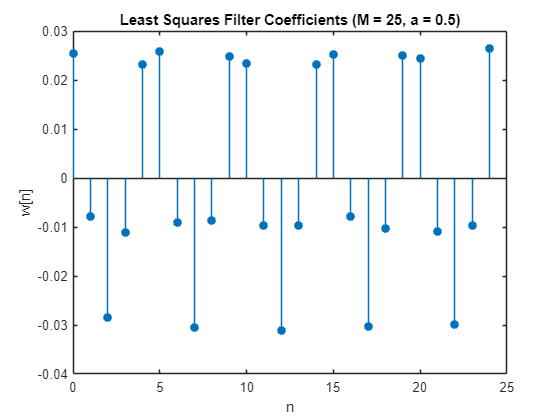

M = 25;
L = 1000;
a = 0.5;
N = M + L - 1;
n = 0:N-1;

x = cos(2*pi*0.2*n) + cos(2*pi*0.24*n) + a*randn(1, N);
d = 0.4*cos(2*pi*0.2*n + pi/5);

% Construct matrix X (each row: x_n to x_{n+M-1})
X = zeros(L, M);
for i = 1:L
    X(i, :) = x(i+M-1:-1:i);  % Time-reversed window
end

d_vec = d(M:end)';  % Length-L vector of desired outputs

% Least squares solution
R = X' * X;
P = X' * d_vec;
w = R \ P;  % Filter coefficients

% Sum of squared error
J = norm(X*w - d_vec)^2;

%impulse response
figure;
stem(0:M-1, w, 'filled');
title(['Least Squares Filter Coefficients (M = ', num2str(M), ', a = ', num2str(a), ')']);
xlabel('n'); ylabel('w[n]');

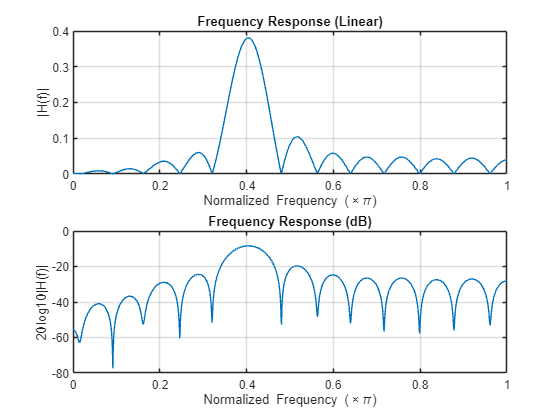


[H, f] = freqz(w, 1, 1024);
mag = abs(H);
mag_dB = 20*log10(mag);

%Frequency Response (abs)
figure;
subplot(2,1,1);
plot(f/pi, mag);
title('Frequency Response (Linear)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('|H(f)|');
grid on;

subplot(2,1,2);
plot(f/pi, mag_dB);
title('Frequency Response (dB)');
xlabel('Normalized Frequency (\times\pi)'); 
ylabel('20log10|H(f)|');
grid on;


[max_gain, idx_max] = max(mag);
f_max = f(idx_max)/pi;

[H_check, ~] = freqz(w, 1, [0.2 0.24]*pi);
gain_at_02 = abs(H_check(1));
gain_at_024 = abs(H_check(2));

fprintf('M = %d, a = %.2f\n', M, a);

M = 25, a = 0.50


fprintf('Sum of squared error J(w): %.4f\n', J);

Sum of squared error J(w): 2.7379


fprintf('Max gain: %.4f at normalized freq = %.4fπ\n', max_gain, f_max);

Max gain: 0.3807 at normalized freq = 0.4043π


fprintf('Gain at 0.2π: %.4f\n', gain_at_02);

Gain at 0.2π: 0.0335


fprintf('Gain at 0.24π: %.4f\n', gain_at_024);

Gain at 0.24π: 0.0102


For problem 6, the sum of squared error was higher for each four different configurations. Also the gain at .24pi was always lower than .2pi for problem 6. On problem 5, the gain for .38pi was always higher than .2pi.

Because .24pi is closer to .2pi, the smaller M doesn't work as well, especially when noise is increased. In conclusion, a high frequency resolution (seen on low order filters) causes more problems for Problem 6.